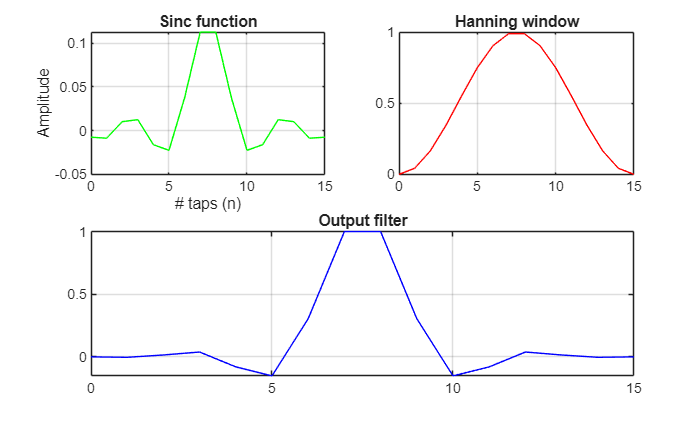

clear all; close all; clc;

%% Filter Design
% Parameters
Nbranches = 4;              % Number of branches in the polyphase filter
Ntaps = 4;                  % Number of taps per filter branch
N = Nbranches*Ntaps;
Tsample = 4;                % Sampling time
BP = 1/Tsample;             % Bandwidth
chann_w = BP/Nbranches;     % Channel width for each branch
filter_chunk = Nbranches;
n = 0:N-1;
center = n - (N-1)/2;       % Centers filter coefficients for output (i.e. 1,16 -> -8,8)

% Sinc Function
sinc_function = zeros(1, N);
for i = 1:N
    if center(i) == 0
        sinc_function(i) = 2*chann_w;
    else
        sinc_function(i) = sin(2*pi*chann_w*Tsample*center(i)) / (pi*Tsample*center(i));
    end
end

% Generate hanning window
hann = 0.5 - 0.5*cos(2*pi*n/(N-1));

% Create filter and normalize
filter = sinc_function .* hann;
normal_filter = filter/max(filter(:));

% Display outputs
figure('Name', 'Filter Design', 'NumberTitle', 'off');
subplot(2,2,1);
plot(n, sinc_function, 'g');
grid on;
title('Sinc function');
xlabel('# taps (n)');
ylabel('Amplitude');

subplot(2,2,2)
plot(n, hann, 'r');
title('Hanning window');
grid on;

subplot(2,2,[3,4])
plot(n, normal_filter, 'b');
title('Output filter')
grid on;

Input signal: Impulse at position 1



DEBUG - Xk_matrix for impulse 1:


     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0



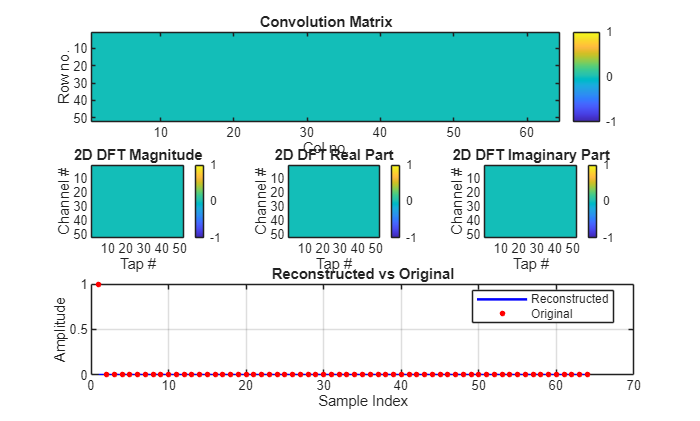

Input signal: Impulse at position 2


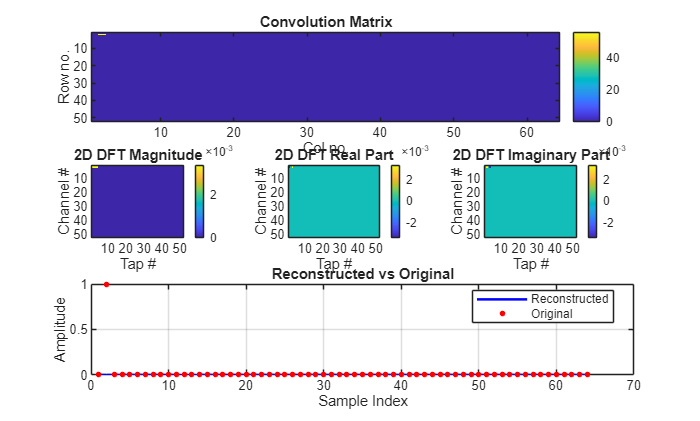

Input signal: Impulse at position 3


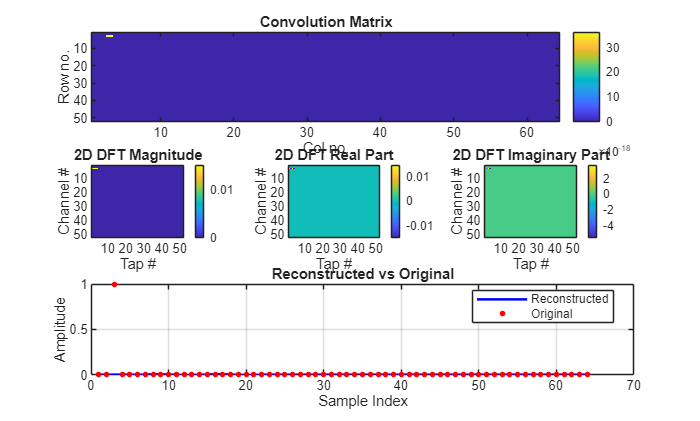

Input signal: Impulse at position 4


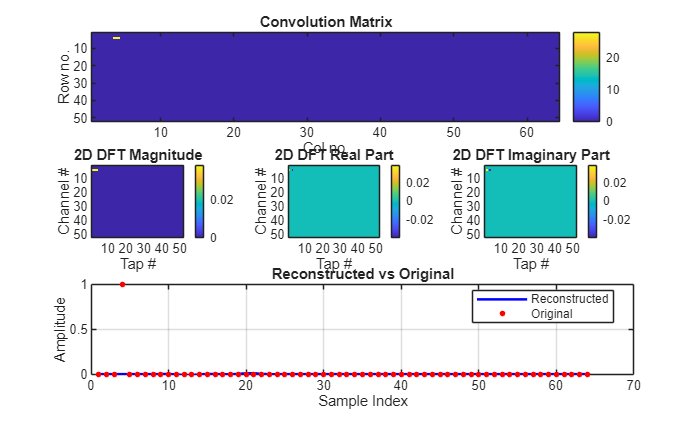

Input signal: Impulse at position 5


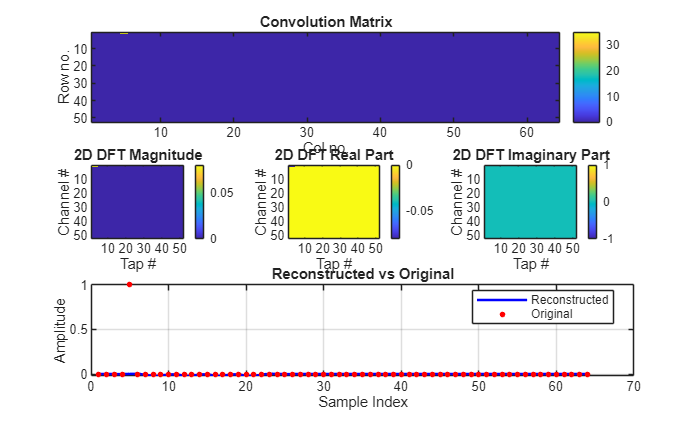

Input signal: Impulse at position 6


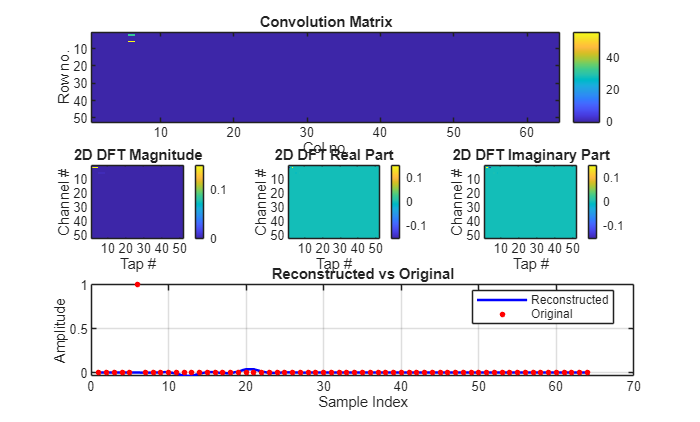

Input signal: Impulse at position 7


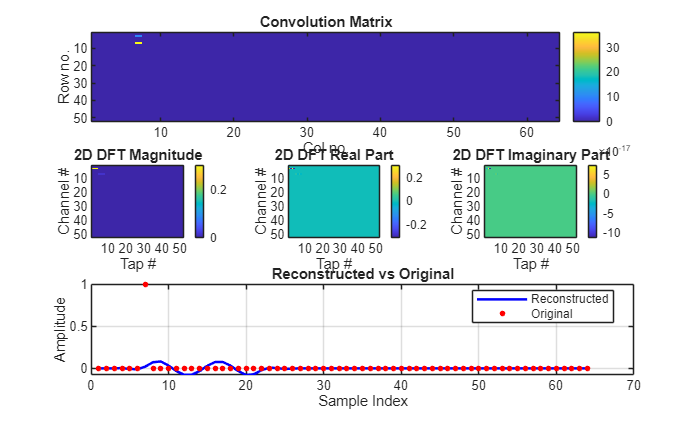

Input signal: Impulse at position 8


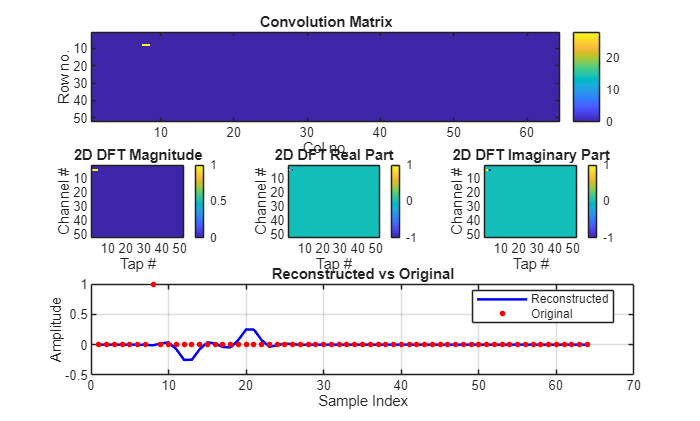

Input signal: Impulse at position 9


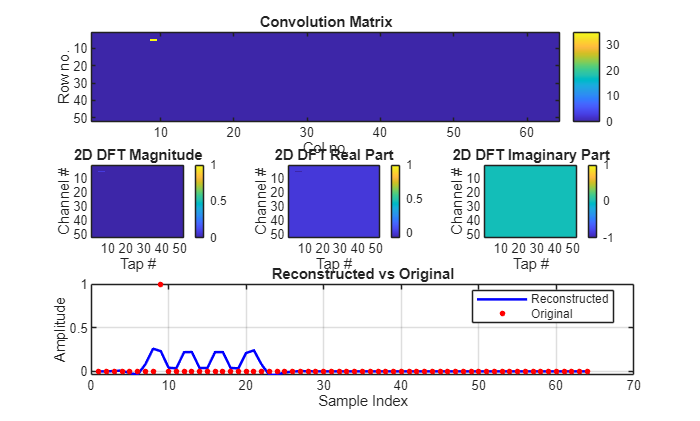

Input signal: Impulse at position 10


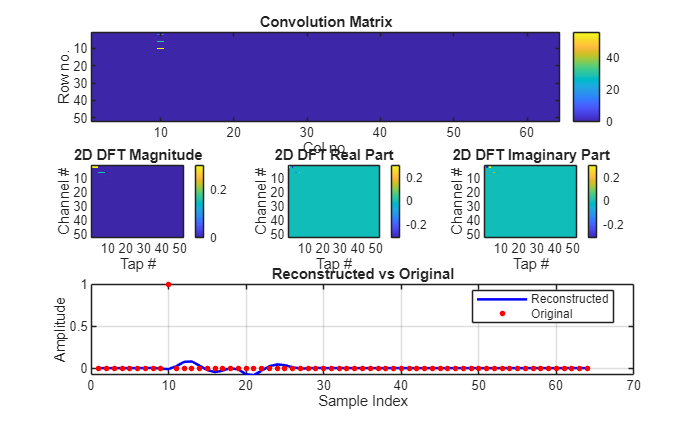

Input signal: Impulse at position 11


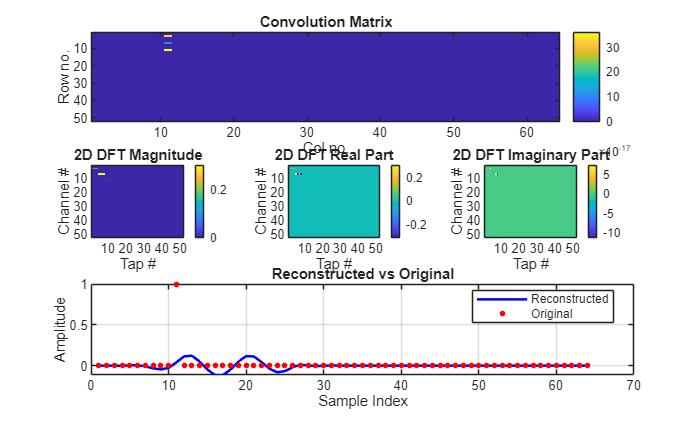

Input signal: Impulse at position 12


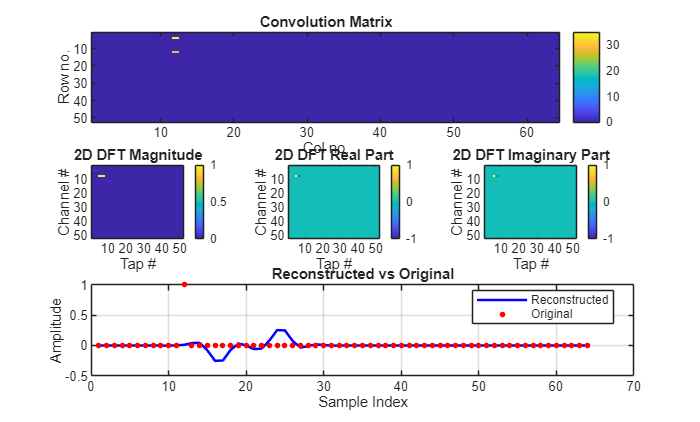

Input signal: Impulse at position 13


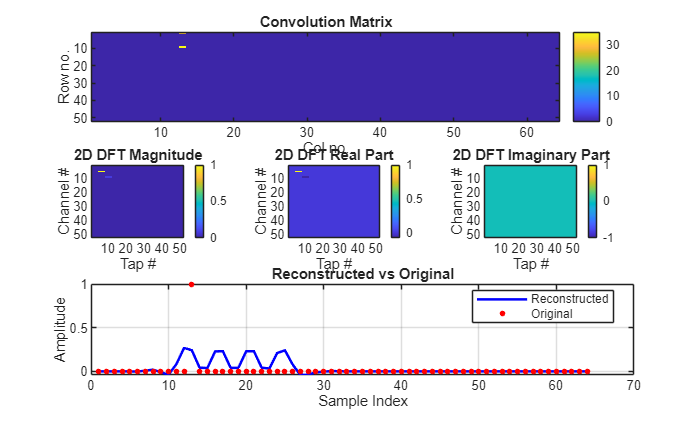

Input signal: Impulse at position 14


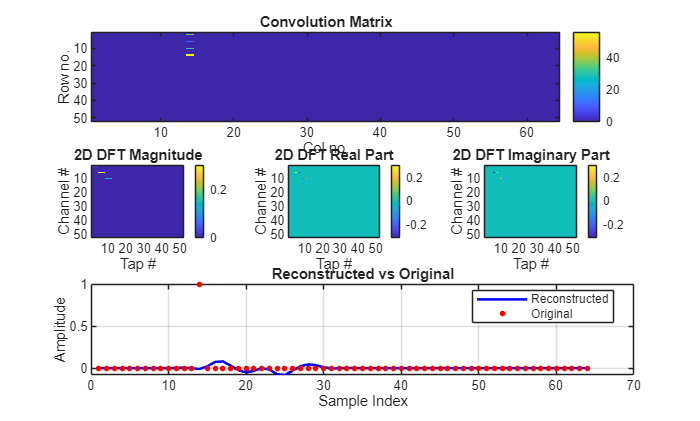

Input signal: Impulse at position 15


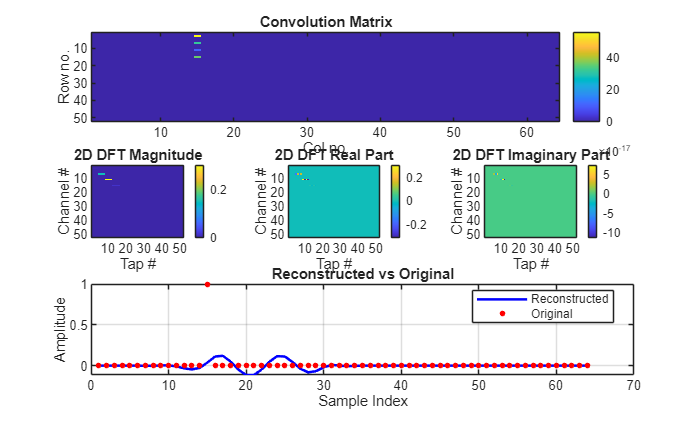

Input signal: Impulse at position 16


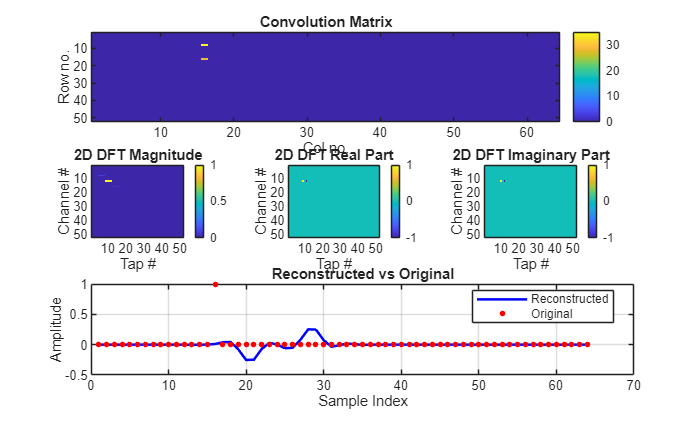

Input signal: Impulse at position 17


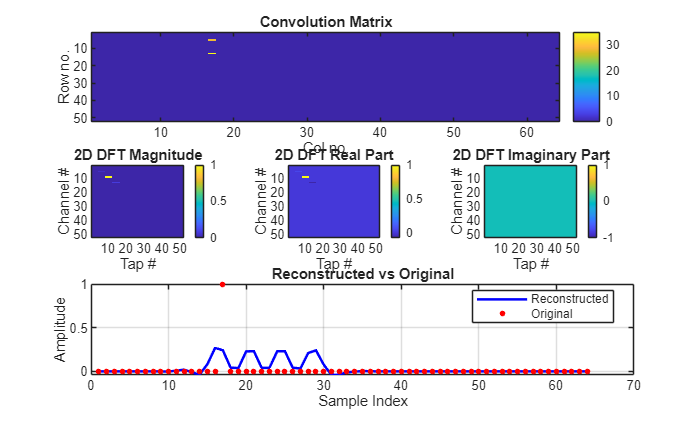

Input signal: Impulse at position 18


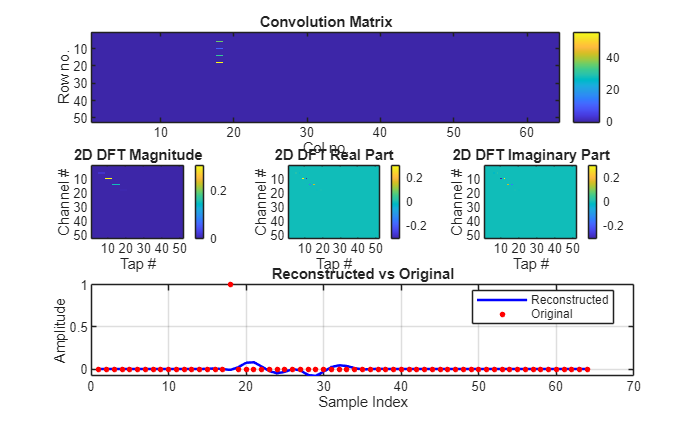

Input signal: Impulse at position 19


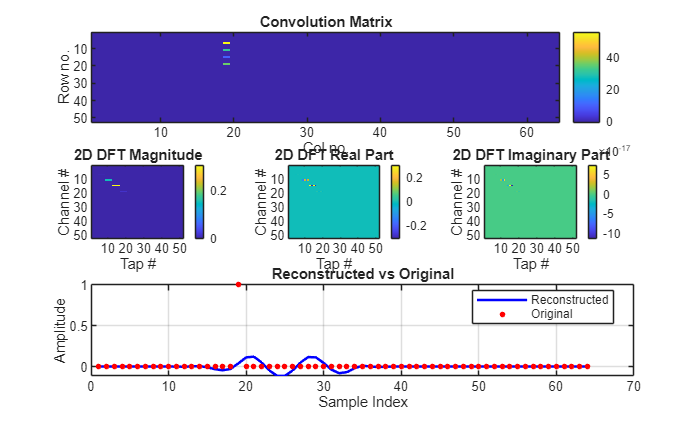

Input signal: Impulse at position 20


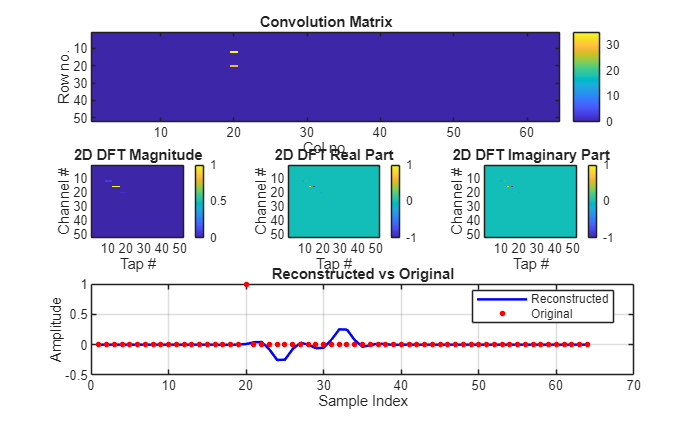

Input signal: Impulse at position 21


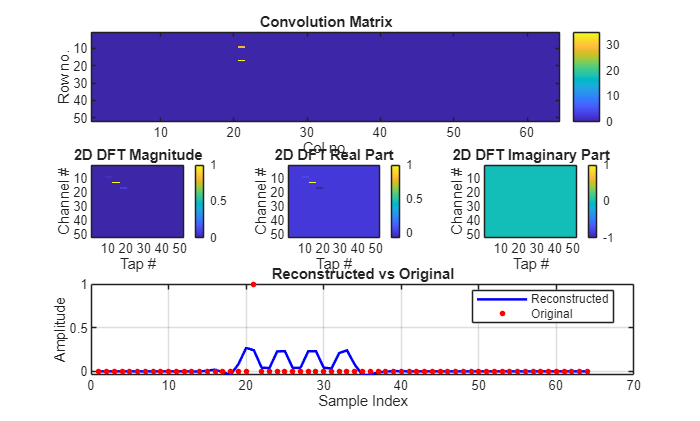

Input signal: Impulse at position 22


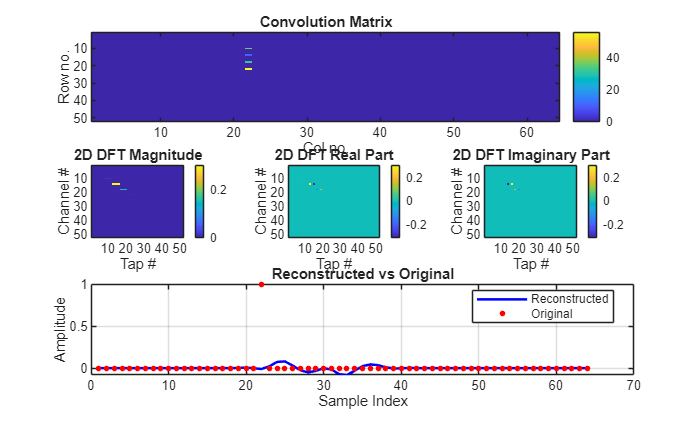

Input signal: Impulse at position 23


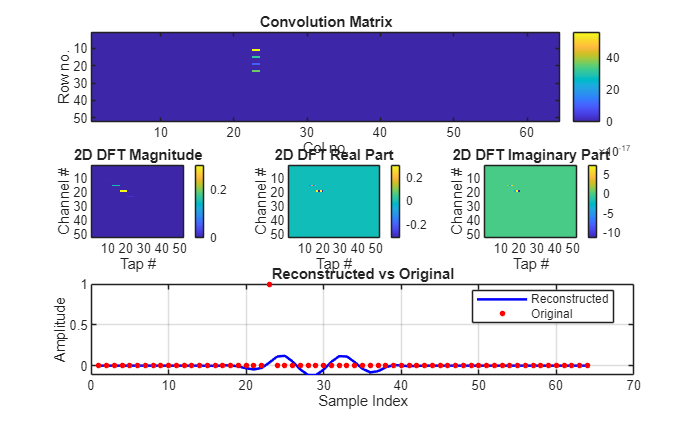

Input signal: Impulse at position 24


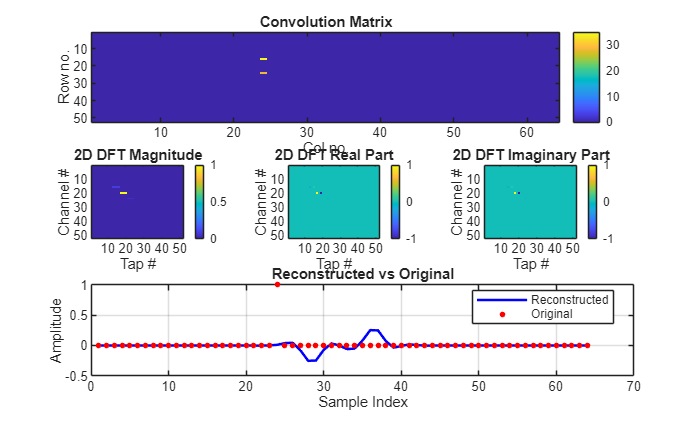

Input signal: Impulse at position 25


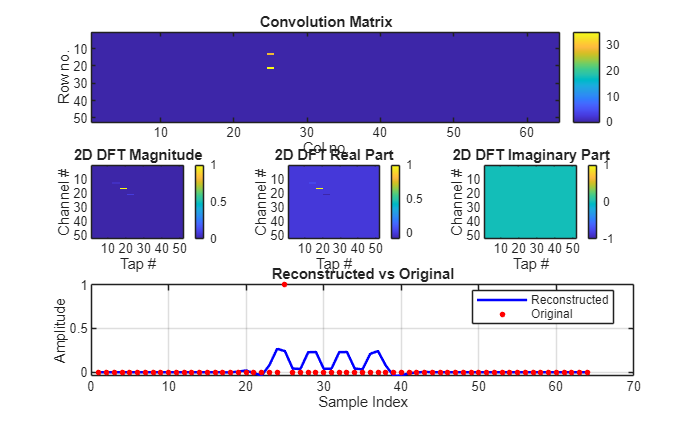

Input signal: Impulse at position 26


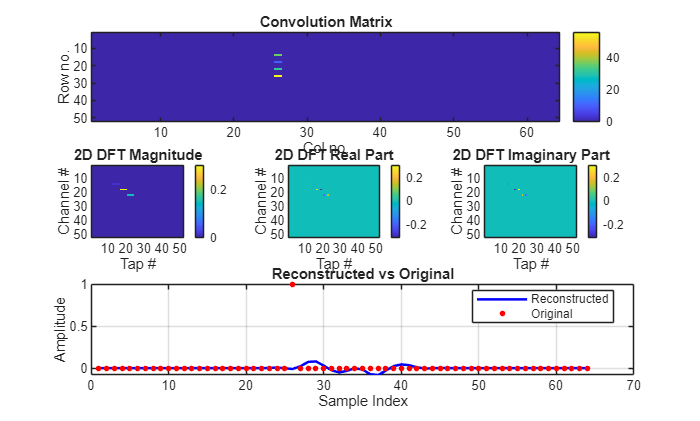

Input signal: Impulse at position 27


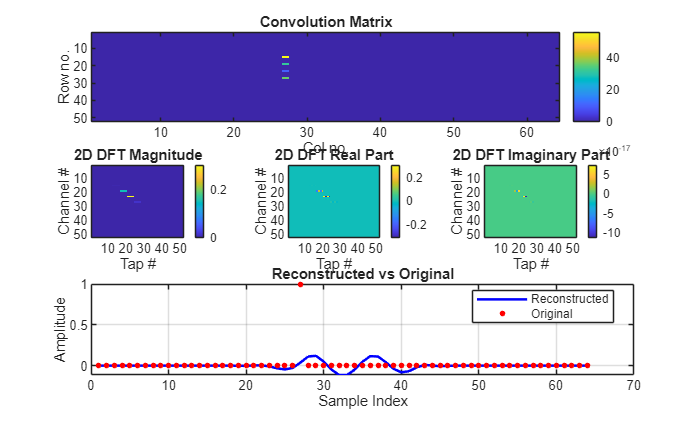

Input signal: Impulse at position 28


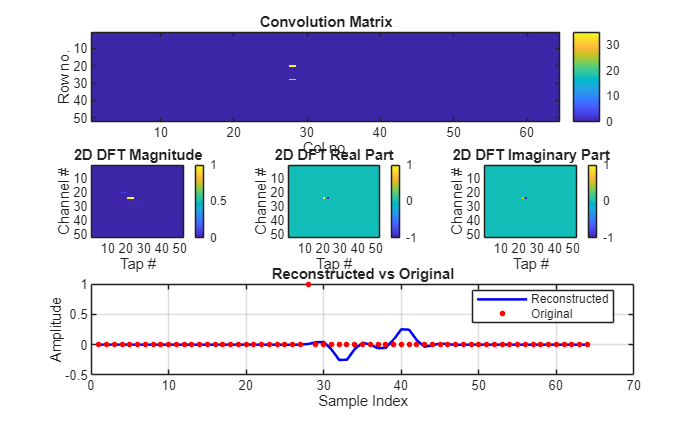

Input signal: Impulse at position 29


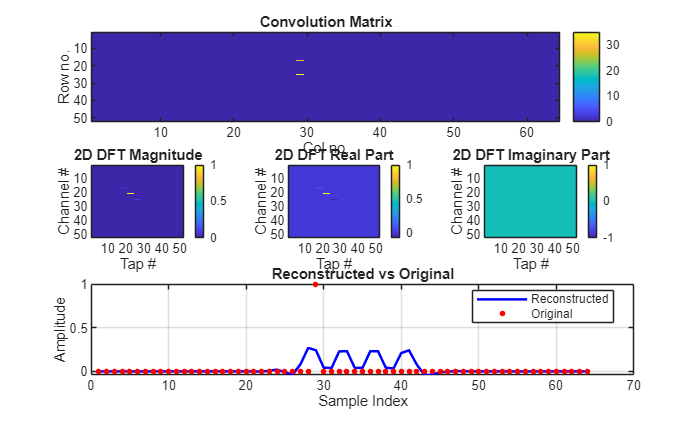

Input signal: Impulse at position 30


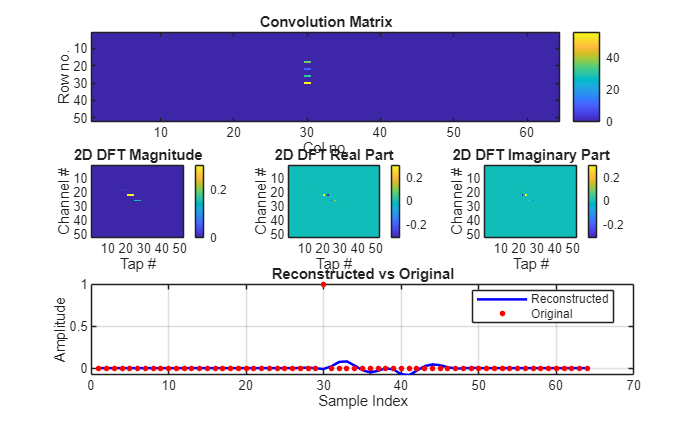

Input signal: Impulse at position 31


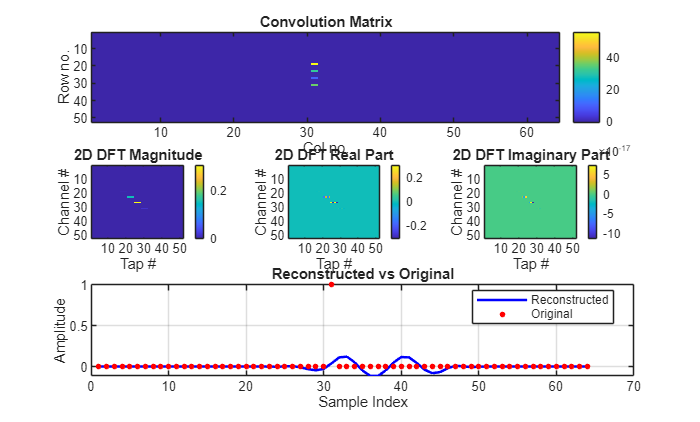

Input signal: Impulse at position 32


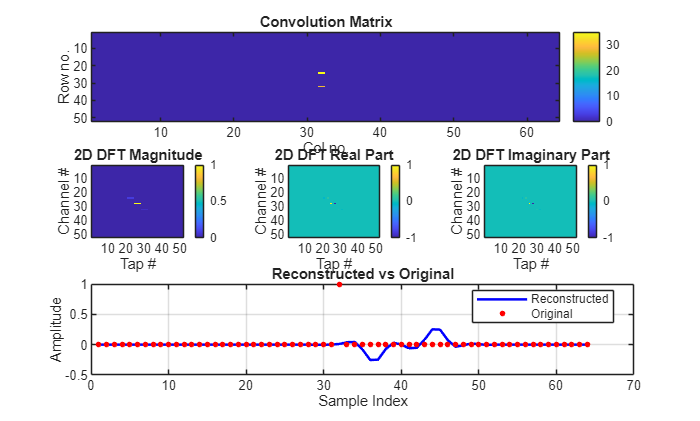

Input signal: Impulse at position 33


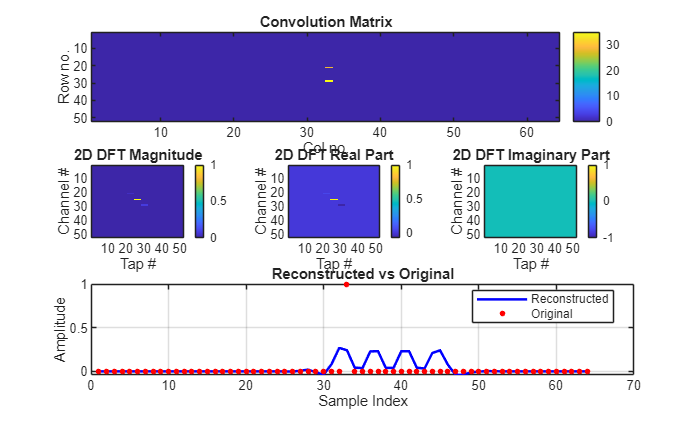

Input signal: Impulse at position 34


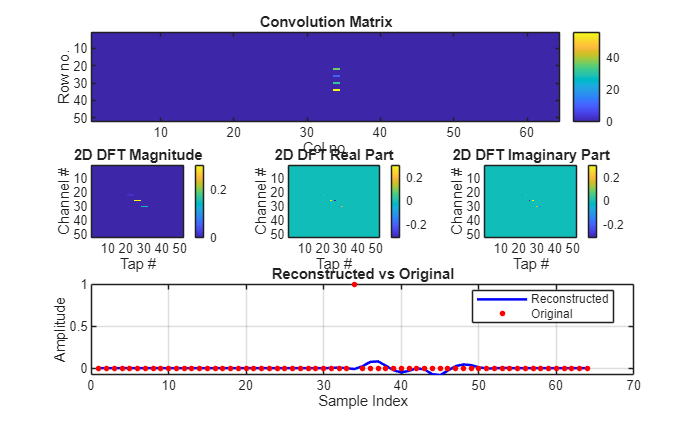

Input signal: Impulse at position 35


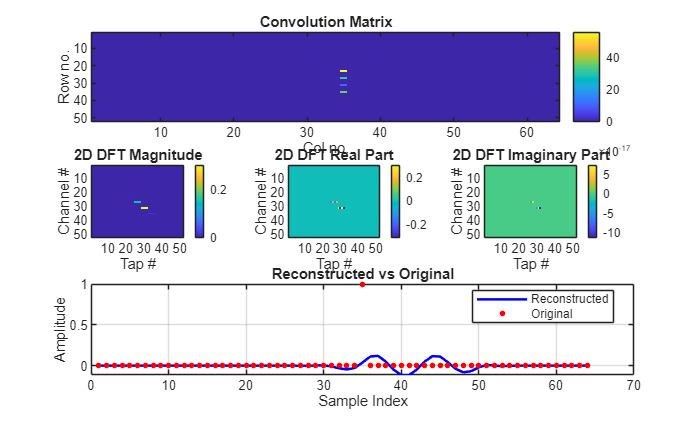

Input signal: Impulse at position 36


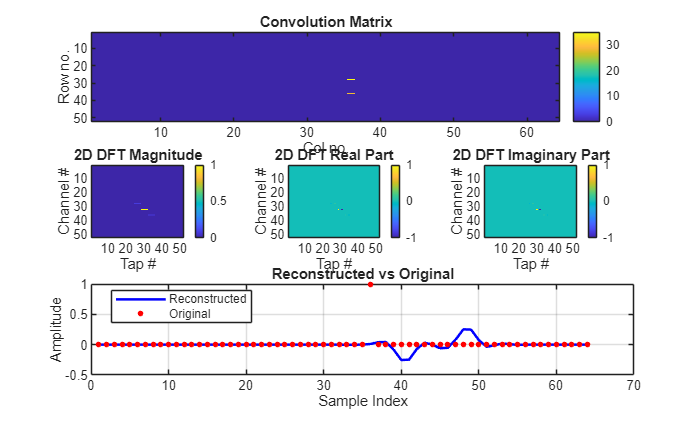

Input signal: Impulse at position 37


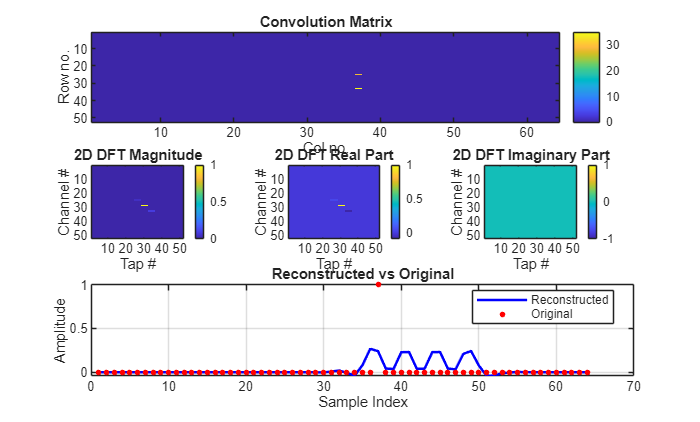

Input signal: Impulse at position 38


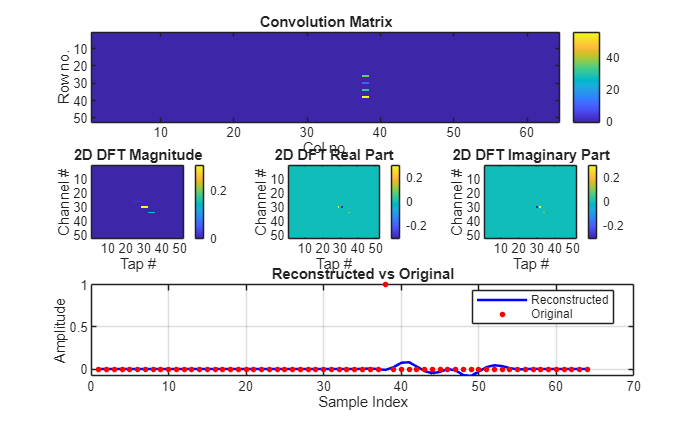

Input signal: Impulse at position 39


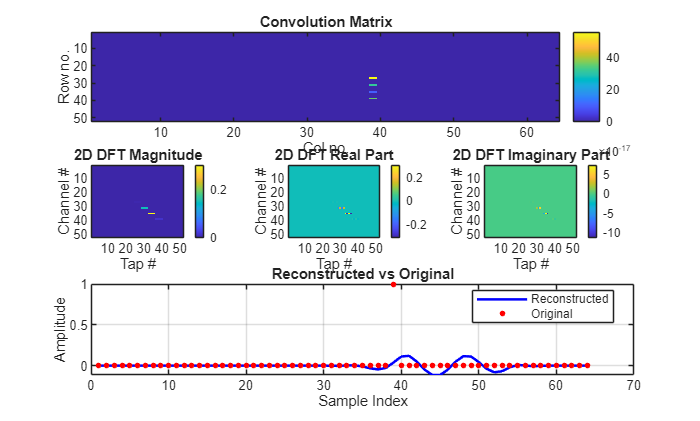

Input signal: Impulse at position 40


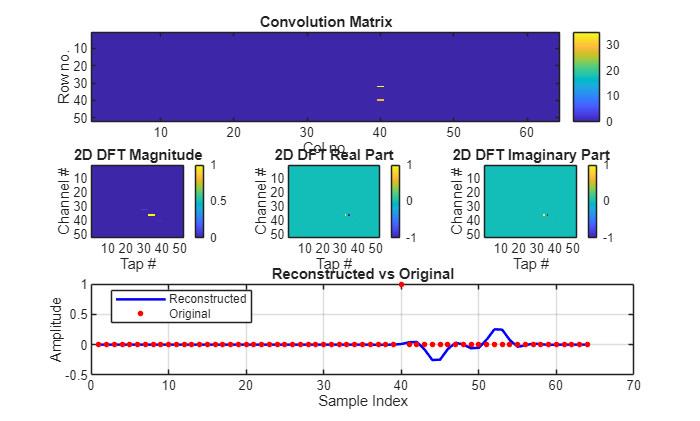

Input signal: Impulse at position 41


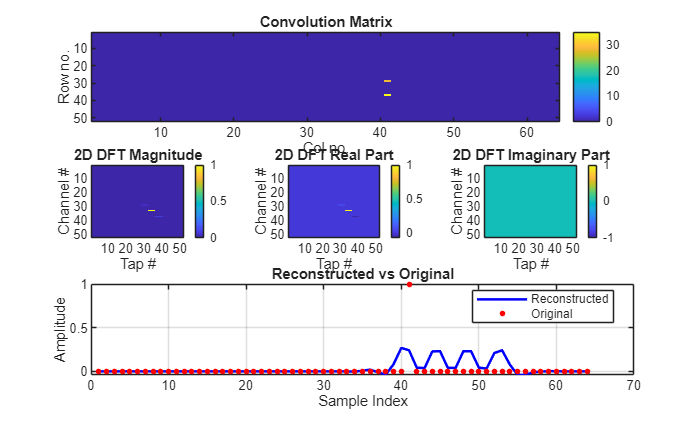

Input signal: Impulse at position 42


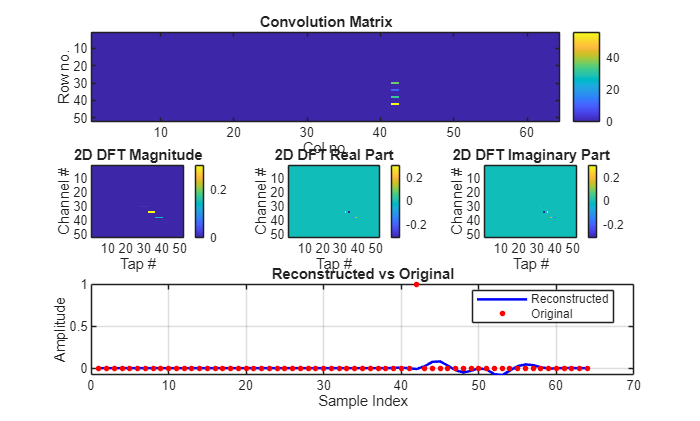

Input signal: Impulse at position 43


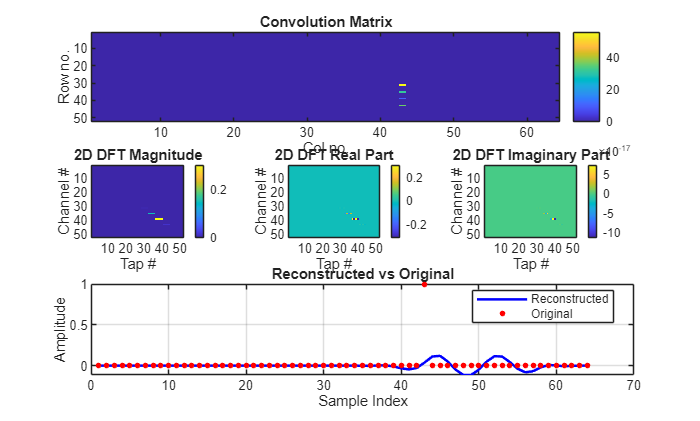

Input signal: Impulse at position 44


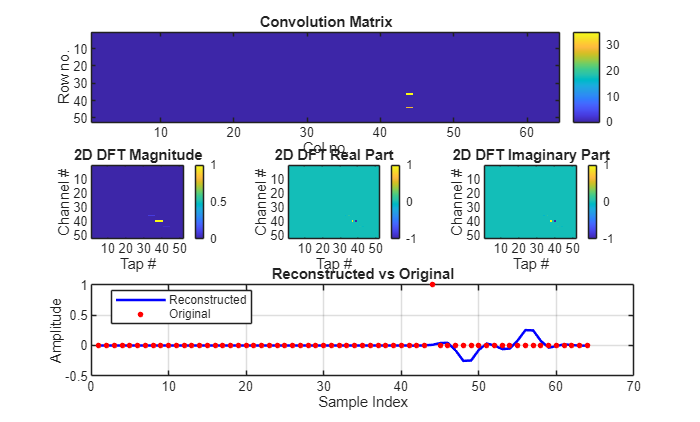

Input signal: Impulse at position 45


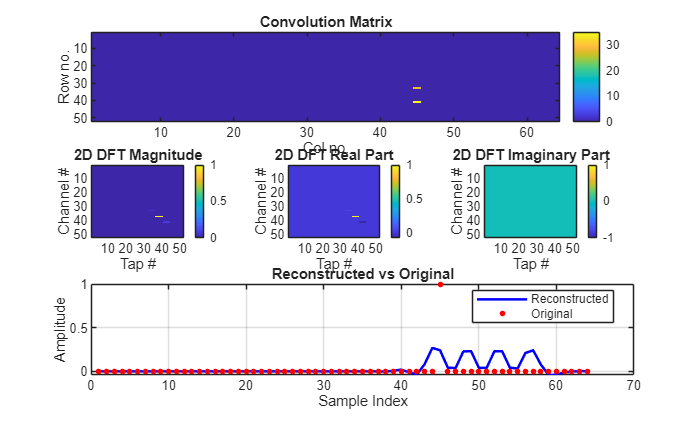

Input signal: Impulse at position 46


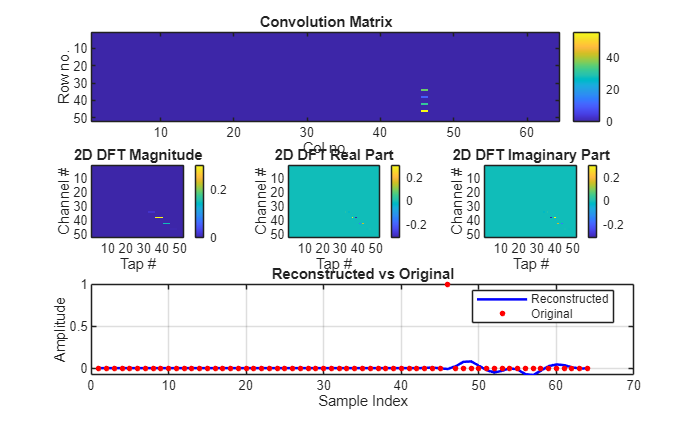

Input signal: Impulse at position 47


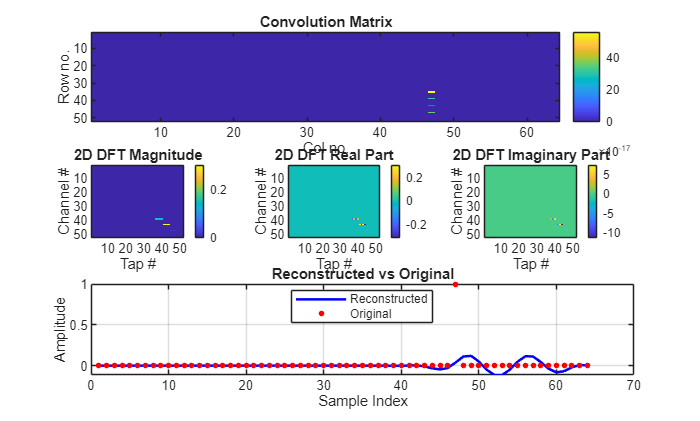

Input signal: Impulse at position 48


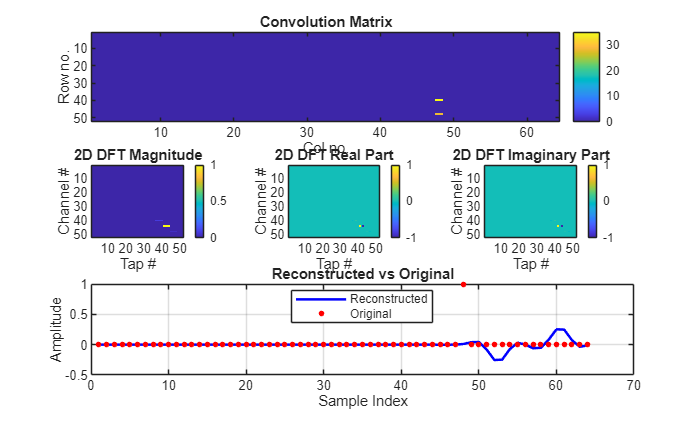

Input signal: Impulse at position 49


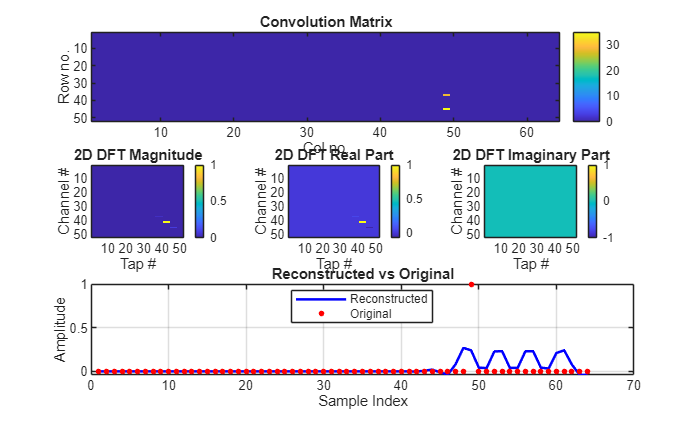

Input signal: Impulse at position 50


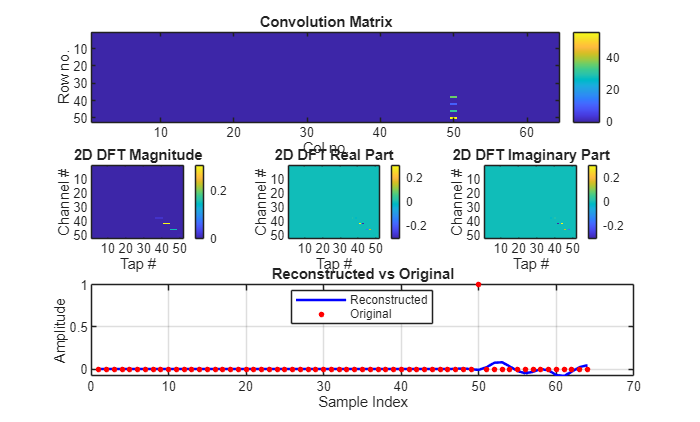

Input signal: Impulse at position 51


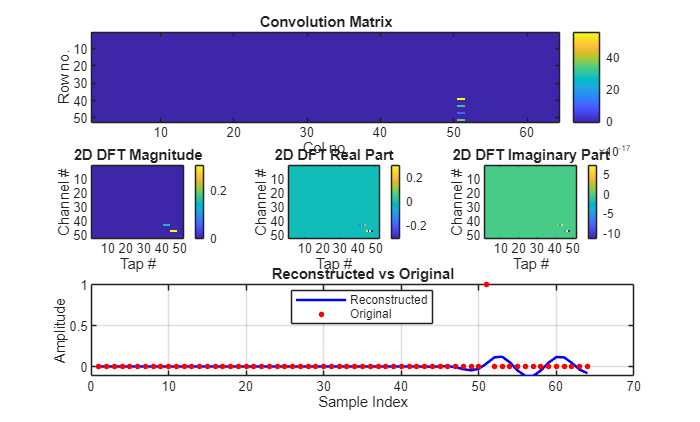

Input signal: Impulse at position 52


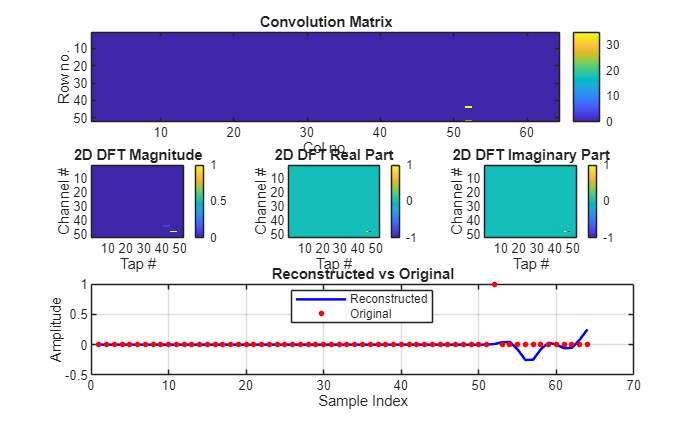

Input signal: Impulse at position 53


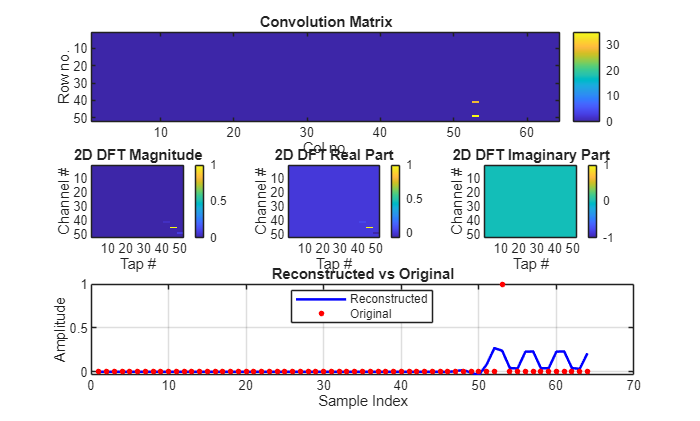

Input signal: Impulse at position 54


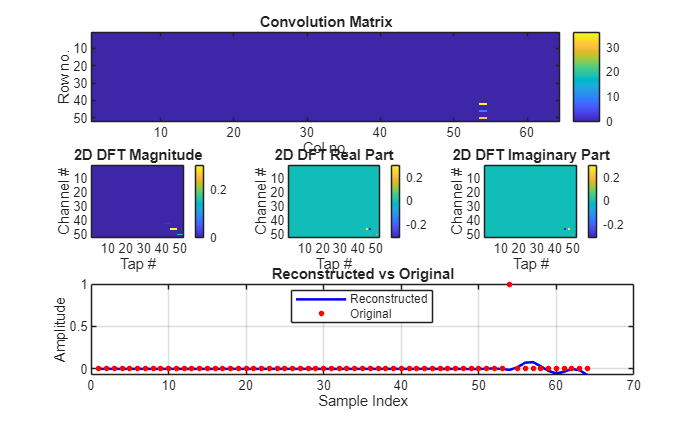

Input signal: Impulse at position 55


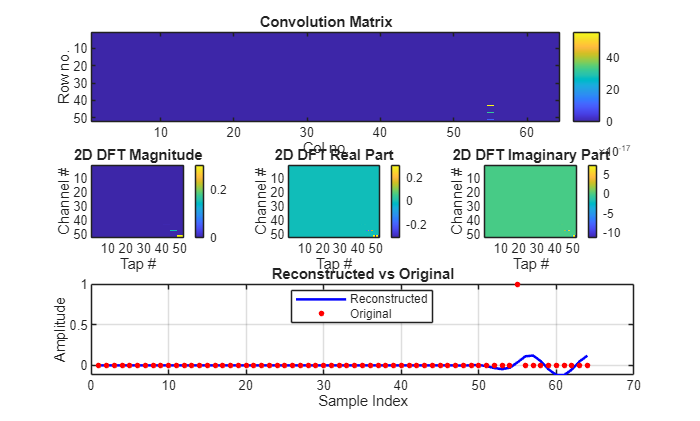

Input signal: Impulse at position 56


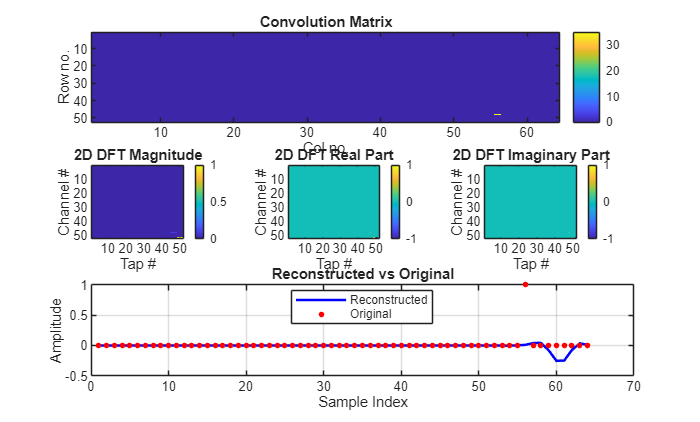

Input signal: Impulse at position 57


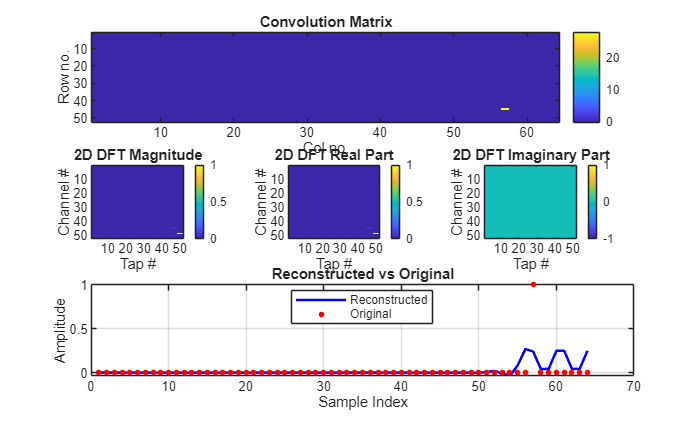

Input signal: Impulse at position 58


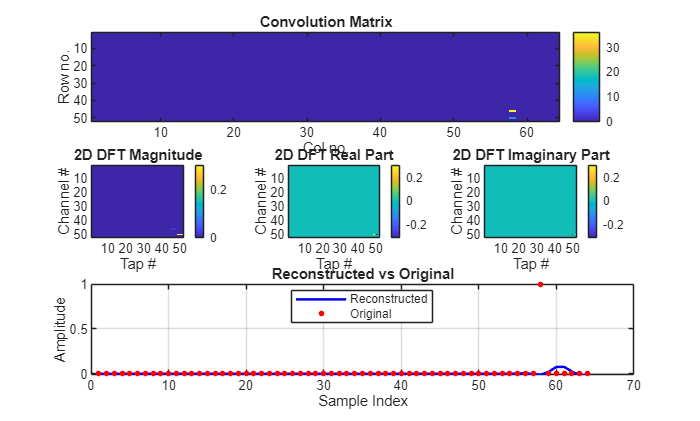

Input signal: Impulse at position 59


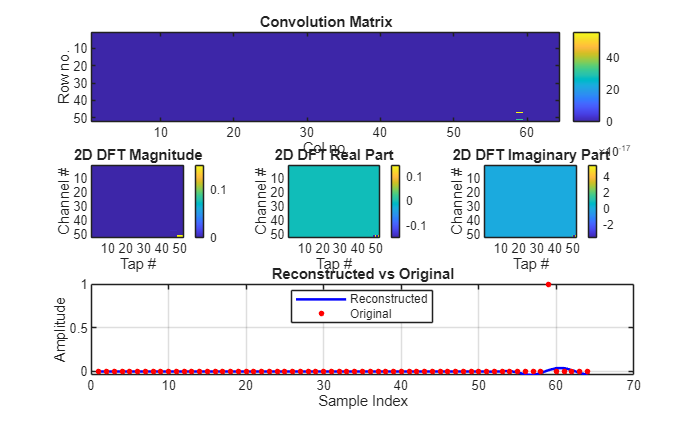

Input signal: Impulse at position 60


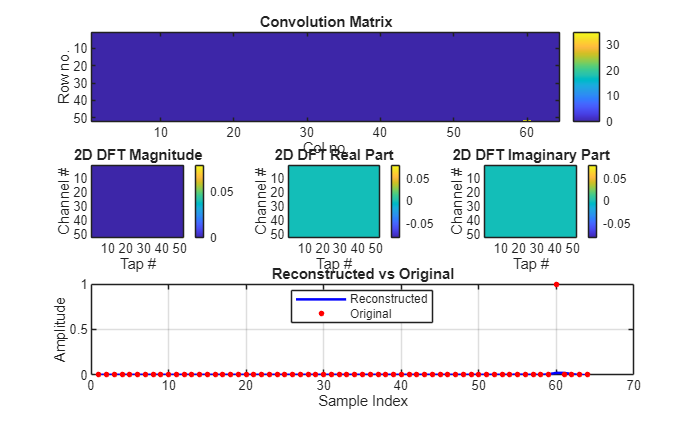

Input signal: Impulse at position 61


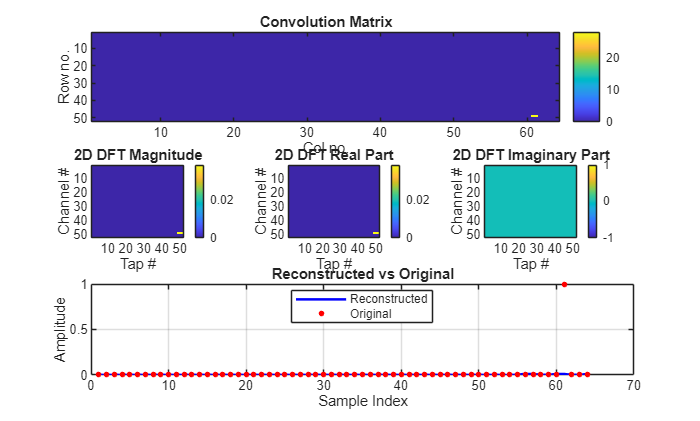

Input signal: Impulse at position 62


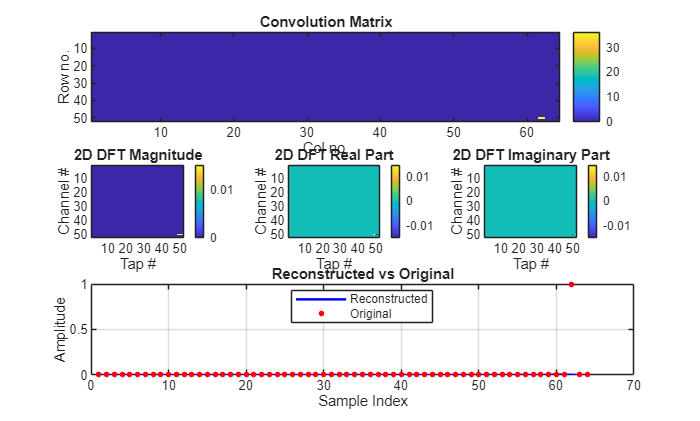

Input signal: Impulse at position 63


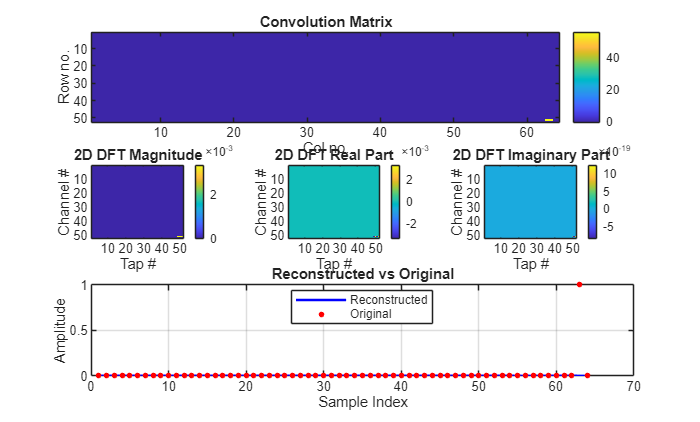

Input signal: Impulse at position 64


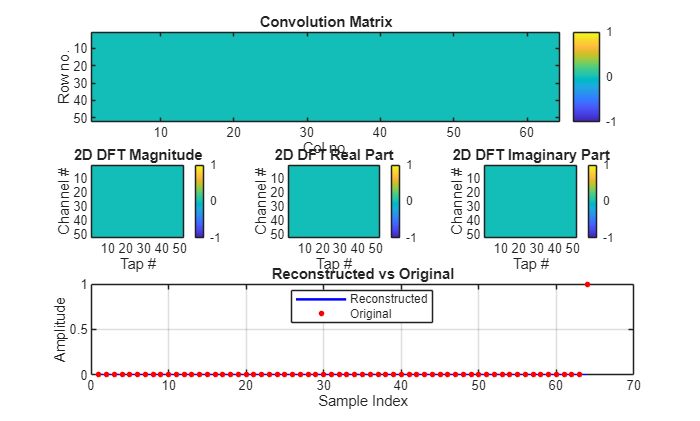


%% Input signal generation
clear length
N_filter = length(normal_filter);
fs = 100;
T = N_filter/fs;
t = (0:(N_filter)*4-1);

%2d fft
N_dft = filter_chunk;
W = zeros(N_dft, N_dft);

for k = 0:N_dft-1
    for n = 0:N_dft-1
        W(k+1, n+1) = exp(-2*pi*1j*k*n/N_dft);
    end
end

%2d ifft
W_inv = zeros(N_dft, N_dft);

for n = 0:N_dft-1
    for k = 0:N_dft-1
        W_inv(n+1, k+1) = (1/N_dft) * exp(2*pi*1j*k*n/N_dft);
    end
end

all_reconstructed_signals = cell(length(t), 1);
all_Xk_matrices = cell(length(t), 1);  % Store Xk_matrix for each impulse

for impulse_pos = 1:length(t)
    
    % Create impulse signal
    input_signal = zeros(1, length(t));
    input_signal(impulse_pos) = 1;
    fprintf('Input signal: Impulse at position %d\n', impulse_pos);
    
    % Parameters + Pre-allocation
    num_full_blocks = floor(length(input_signal) / filter_chunk);               
    mat_its = floor((length(input_signal) - N_filter) / filter_chunk) + 1;      
    stored_matrix = cell(mat_its, 1);                                           
    stored_fft_blocks = cell(mat_its, 1);                                       
    output_cols = mat_its * filter_chunk + N_filter - 4;                        
    output_mat = zeros(mat_its * filter_chunk, output_cols);                    
    padded_length = num_full_blocks * filter_chunk + N_filter - filter_chunk;  
    matrix = zeros(filter_chunk, N_filter);
    fft_matrix = zeros(mat_its*filter_chunk, mat_its*filter_chunk);
    
    % Pad input signal with zeros to handle edge effects
    input_padded = [input_signal, zeros(1, max(0, padded_length - length(input_signal)))];
    
    % Main analysis loop - process input signal in blocks
    for j = 1:mat_its

        startpoint = (j-1) * filter_chunk + 1;
        blockend = startpoint + N_filter - 1;
        values = startpoint:blockend;
        
        % Apply filter to input segment
        Y = input_signal(values) .* normal_filter;    
        
        % Fill matrix with filtered values in polyphase arrangement
        for i = 1:N_filter
            matrix(mod(i-1, filter_chunk) + 1, i) = Y(i);
        end 
        stored_matrix{j} = matrix;
    
        % Place matrix block into overall output matrix
        row_start = (j-1) * filter_chunk + 1;
        row_end = j * filter_chunk;
        col_start = (j-1) * filter_chunk + 1;
        col_end = col_start + N_filter - 1;   
        if col_end <= output_cols
            output_mat(row_start:row_end, col_start:col_end) = stored_matrix{j};
        end
    end
    
    % Apply matrix-based 2D DFT to each stored matrix block
    for i = 1:mat_its
        % Create diagonal matrix from row sums and apply 2D filter
        dft_block = W.*sum(stored_matrix{i},2);
        
        % Reshape back to 2D block
        currentblock = reshape(dft_block, filter_chunk, filter_chunk);
        stored_fft_blocks{i} = currentblock;
    
        % Place FFT block into overall FFT matrix
        blockstart = (i-1)*filter_chunk + 1;
        blockend = i*filter_chunk;
        fft_matrix(blockstart:blockend, blockstart:blockend) = currentblock;
    end
    
    % Extract Xk[m] from fft_matrix structure
    K = filter_chunk;
    M = K;  % Decimation/interpolation factor
    Xk_matrix = zeros(K, mat_its);
    
    % Extract frequency domain samples from diagonal blocks
    for m = 1:mat_its
        blockstart = (m-1)*K + 1;
        blockend = m*K;
        
        % Get the m-th diagonal block from fft_matrix
        freq_block = fft_matrix(blockstart:blockend, blockstart:blockend);
        Xk_matrix(:, m) = diag(freq_block);
    end
    
    % Initialize output signal
    output_length = length(input_signal) + N_filter;
    reconostructed_signal = zeros(1, output_length);
    
    % Synthesis filter
    synthesis_filter = normal_filter;
    
    % Process each time block m
    for m = 0:(mat_its-1)
        if m+1 <= size(Xk_matrix, 2)
            Xk_m = Xk_matrix(:, m+1);
            
            % IDFT: Properly multiply W_inv matrix with frequency samples
            time_samples = W_inv * Xk_m;
                        
            %Zero-pad length of signal (upsample by M)
            upsampled_length = K * M;
            upsampled = zeros(1, upsampled_length);
            upsampled(1:M:end) = time_samples;
            
            % Conv. with synthesis filter (reverse-time input filter)
            filtered = conv(upsampled, synthesis_filter);
            
            %Time shifting and add individual sums together
            time_shift = m * M;
            output_start = time_shift + 1;
            output_end = min(output_start + length(filtered) - 1, output_length);
            valid_length = output_end - output_start + 1;
            
            % Overlap-add (implements the sum over m)
            reconostructed_signal(output_start:output_end) = ...
                reconostructed_signal(output_start:output_end) + real(filtered(1:valid_length));
        end
    end
    
    % Trim to input signal length
    reconostructed_signal = reconostructed_signal(1:length(input_signal));
    
    num_polyphase_taps = N/K;
    analysis_polyphase = zeros(K, num_polyphase_taps);
    synthesis_polyphase = zeros(K, num_polyphase_taps);
    
    for k = 0:K-1
        analysis_polyphase(k+1, :) = normal_filter(k+1:K:end);
        synthesis_polyphase(k+1, :) = synthesis_filter(k+1:K:end);
    end
    
    % Check condition: sum_m fm[n] * hm[-n]
    PR_check = zeros(1, 2*num_polyphase_taps - 1);
    for m = 1:K
        PR_check = PR_check + conv(synthesis_polyphase(m, :), fliplr(analysis_polyphase(m, :)));
    end
    
    % Normalize and analyze
    [peak_val, peak_idx] = max(abs(PR_check));
    PR_normalized = PR_check / peak_val;
    sidelobe_energy = sum(abs(PR_normalized).^2) - abs(PR_normalized(peak_idx))^2;
    
    % DO NOT apply per-impulse gain correction here!
    % We need the raw system response to build the synthesis matrix
    RealPart = reconostructed_signal;
    
    % Store both the reconstructed signal and the Xk_matrix
    all_reconstructed_signals{impulse_pos} = reconostructed_signal;
    all_Xk_matrices{impulse_pos} = Xk_matrix;
    
    logforgraph = abs(20*log10(output_mat));
    [r,c] = size(logforgraph);
    for i = 1:r
        for j = 1:c
            if logforgraph(i,j) == Inf
                logforgraph(i,j) = 0;
            end
        end
    end
    
    h=figure;
    
    % Convolution Matrix Heatmap
    subplot(3,3,[1,2,3]);
    imagesc(logforgraph);
    colormap('parula');
    colorbar;
    xlabel('Col no.')
    ylabel('Row no.')
    title('Convolution Matrix');
    
    % FFT Magnitude
    subplot(3,3,4);
    imagesc(abs(fft_matrix));
    colormap('parula');
    colorbar;
    xlabel('Tap #');
    ylabel('Channel #');
    title('2D DFT Magnitude');
    
    % FFT Real Part
    subplot(3,3,5);
    imagesc(real(fft_matrix));
    colormap('parula');
    colorbar;
    xlabel('Tap #');
    ylabel('Channel #');
    title('2D DFT Real Part');
    
    % FFT Imaginary Part
    subplot(3,3,6);
    imagesc(imag(fft_matrix));
    colormap('parula');
    colorbar;
    xlabel('Tap #');
    ylabel('Channel #');
    title('2D DFT Imaginary Part');
    
    % Reconstructed vs Original
    subplot(3,3,[7,8,9]);
    plot(1:length(RealPart), RealPart, 'b-', 'LineWidth', 1.5, 'MarkerSize', 6);
    hold on;
    plot(1:length(input_signal), input_signal, 'r.', 'MarkerSize', 10);
    title('Reconstructed vs Original');
    xlabel('Sample Index')
    ylabel('Amplitude')
    legend('Reconstructed', 'Original', 'Location', 'best');
    grid on;

    saveas(h, sprintf('pfb_%02d.png', impulse_pos))
end

## Build Synthesis Matrix

K = filter_chunk;  % Nbranches = 4
input_length = length(t);  % 16


Actual dimensions from impulse testing:


  Input length: 64


  Xk_matrix size: 4 × 13


  Reconstruction length: 64


  mat_its (actual): 13


% The synthesis matrix should map from flattened Xk to reconstruction
num_freq_bins = numel(first_Xk);  % Total frequency domain values
output_length = length(first_reconstruction);

fprintf('\nBuilding synthesis matrix: %d × %d\n', output_length, num_freq_bins);


Building synthesis matrix: 64 × 52



% Collect data from all impulses
all_Xk_flat = zeros(input_length, num_freq_bins);
all_outputs = zeros(input_length, output_length);

for impulse_pos = 1:input_length
    Xk_mat = all_Xk_matrices{impulse_pos};
    all_Xk_flat(impulse_pos, :) = Xk_mat(:)';  % Flatten to row
    
    reconstructed = all_reconstructed_signals{impulse_pos};
    all_outputs(impulse_pos, :) = reconstructed;
end

synthesis_matrix_transpose = (all_Xk_flat' * all_Xk_flat) \ (all_Xk_flat' * all_outputs);
synthesis_matrix = synthesis_matrix_transpose';

fprintf('Synthesis matrix built: %d × %d\n', size(synthesis_matrix));

Synthesis matrix built: 64 × 52


fprintf('Maps: Xk_flat (1×%d) * synthesis_matrix'' (%d×%d) = output (1×%d)\n', ...
    num_freq_bins, num_freq_bins, output_length, output_length);

Maps: Xk_flat (1×52) * synthesis_matrix' (52×64) = output (1×64)



=== Diagnostic: Raw Matrix Performance ===



for idx = 1:length(test_positions)
    test_pos = test_positions(idx);
    
    % Input impulse
    input_impulse = zeros(1, input_length);
    input_impulse(test_pos) = 1;
    
    % Matrix reconstruction
    Xk_flat_test = all_Xk_flat(test_pos, :);
    reconstructed_matrix = Xk_flat_test * synthesis_matrix_transpose;
    
    % Original reconstruction
    reconstructed_original = all_outputs(test_pos, :);
    
    % Compare
    mse = mean((reconstructed_matrix - reconstructed_original).^2);
    input_rms = rms(input_impulse);
    matrix_rms = rms(reconstructed_matrix);
    original_rms = rms(reconstructed_original);
    
    fprintf('Position %2d: input_rms=%.4f, matrix_rms=%.4f, original_rms=%.4f, MSE=%.2e\n', ...
        test_pos, input_rms, matrix_rms, original_rms, mse);
end

Position  1: input_rms=0.1250, matrix_rms=0.0000, original_rms=0.0000, MSE=0.00e+00
Position 16: input_rms=0.1250, matrix_rms=0.0669, original_rms=0.0669, MSE=3.43e-34
Position 32: input_rms=0.1250, matrix_rms=0.0669, original_rms=0.0669, MSE=1.20e-34
Position 48: input_rms=0.1250, matrix_rms=0.0669, original_rms=0.0669, MSE=5.60e-34
Position 64: input_rms=0.1250, matrix_rms=0.0000, original_rms=0.0000, MSE=0.00e+00



Note: No gain correction applied. Matrix learns raw system response.



%% Verify the synthesis matrix
fprintf('\n=== Verifying Synthesis Matrix ===\n');


=== Verifying Synthesis Matrix ===



% Test with a few impulse positions
test_positions = [1, 7, 16];
total_mse = 0;

for idx = 1:length(test_positions)
    pos = test_positions(idx);
    
    % Get Xk flat for this impulse
    Xk_flat = all_Xk_flat(pos, :);
    
    % Reconstruct using matrix
    reconstructed_matrix = Xk_flat * synthesis_matrix_transpose;
    
    % Get original reconstruction
    original = all_outputs(pos, :);
    
    % Calculate error
    mse = mean((reconstructed_matrix - original).^2);
    total_mse = total_mse + mse;
    
    fprintf('Impulse position %d: MSE = %.6e\n', pos, mse);
end

Impulse position 1: MSE = 0.000000e+00
Impulse position 7: MSE = 9.041641e-35
Impulse position 16: MSE = 3.433747e-34



Average MSE: 1.445970e-34


✓ Matrix accuracy: PERFECT



=== Saving Synthesis Matrix ===



% Save all relevant matrices and parameters
save('synthesis_matrix.mat', 'synthesis_matrix', 'synthesis_matrix_transpose', ...
     'W', 'W_inv', 'normal_filter', 'K', 'N_filter', 'filter_chunk', ...
     'mat_its', 'input_length', 'output_length');

Saved synthesis_matrix.mat with:


  synthesis_matrix: 64 × 52


  W (FFT matrix): 4 × 4


  W_inv (IFFT matrix): 4 × 4


  Filter parameters and dimensions


%% Visualization
figure('Name', 'Synthesis Matrix Analysis', 'NumberTitle', 'off');

% Matrix visualization
subplot(2,2,1);
imagesc(abs(synthesis_matrix));
colormap('parula');
colorbar;
title(sprintf('Synthesis Matrix (%d × %d)', size(synthesis_matrix)));
xlabel('Frequency Bin');
ylabel('Output Sample');

% Test reconstruction
subplot(2,2,2);
test_pos = 7;
Xk_flat = all_Xk_flat(test_pos, :);
reconstructed_matrix = Xk_flat * synthesis_matrix_transpose;
original = all_outputs(test_pos, :);

plot(1:length(original), original, 'r-', 'LineWidth', 2);
hold on;
plot(1:length(reconstructed_matrix), reconstructed_matrix, 'b--', 'LineWidth', 1.5);

title(sprintf('Reconstruction Test (Impulse %d)', test_pos));
xlabel('Sample');
ylabel('Amplitude');
legend('Original', 'Matrix', 'Location', 'best');
grid on;

% Reconstruction error
subplot(2,2,3);
error = reconstructed_matrix - original;
stem(error, 'k', 'LineWidth', 1.5);

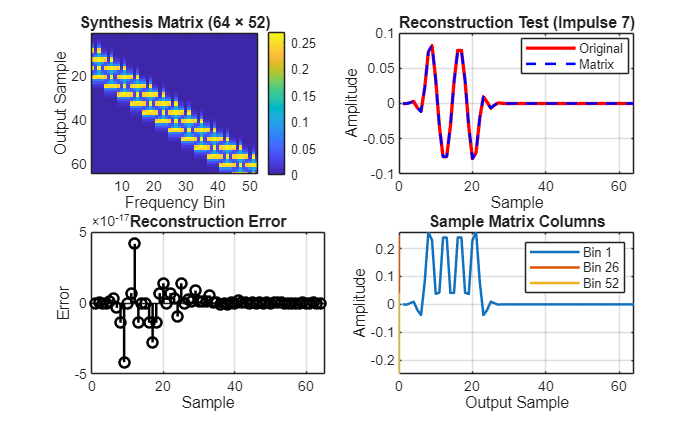

title('Reconstruction Error');
xlabel('Sample');
ylabel('Error');
grid on;

% Matrix structure analysis
subplot(2,2,4);
% Show a few columns of the synthesis matrix
plot(synthesis_matrix(:, 1), 'LineWidth', 1.5, 'DisplayName', 'Bin 1');
hold on;
plot(synthesis_matrix(:, size(synthesis_matrix,2)/2), 'LineWidth', 1.5, 'DisplayName', sprintf('Bin %d', size(synthesis_matrix,2)/2));
plot(synthesis_matrix(:, end), 'LineWidth', 1.5, 'DisplayName', sprintf('Bin %d', size(synthesis_matrix,2)));
hold off;
title('Sample Matrix Columns');
xlabel('Output Sample');
ylabel('Amplitude');
legend('Location', 'best');
grid on;


fprintf('\n=== Synthesis Matrix Complete ===\n');


=== Synthesis Matrix Complete ===


fprintf('Matrix: %d × %d\n', size(synthesis_matrix));

Matrix: 64 × 52


fprintf('Maps: %d frequency values → %d time samples\n', size(synthesis_matrix, 2), size(synthesis_matrix, 1));

Maps: 52 frequency values → 64 time samples


fprintf('Usage: output = Xk_flat * synthesis_matrix''\n');

Usage: output = Xk_flat * synthesis_matrix'


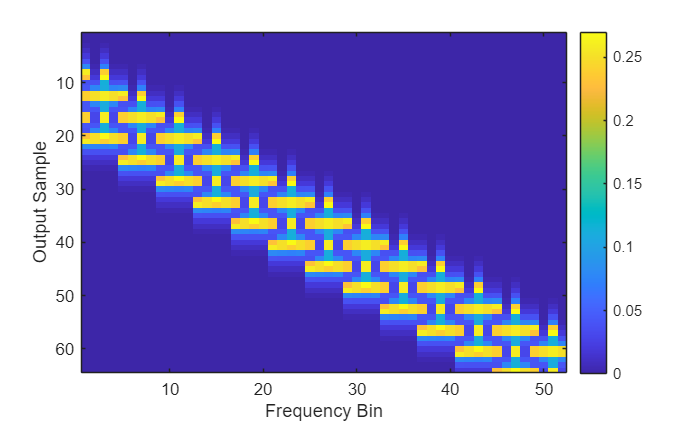


% Matrix visualization
figure;
imagesc(abs(synthesis_matrix));
colormap('parula');
colorbar;
xlabel('Frequency Bin');
ylabel('Output Sample');

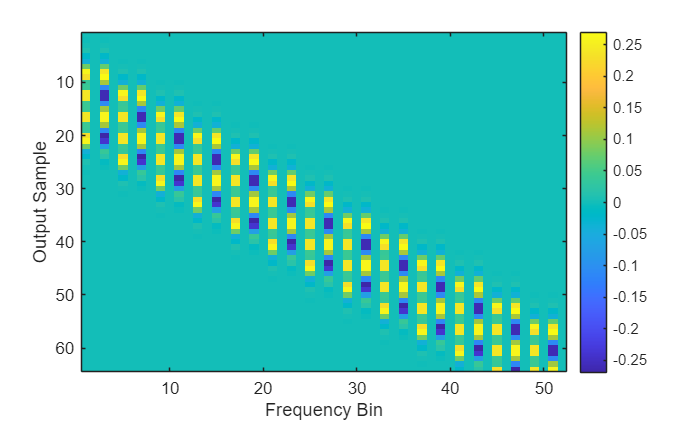


figure;
imagesc(real(synthesis_matrix));
colormap('parula');
colorbar;
xlabel('Frequency Bin');
ylabel('Output Sample');

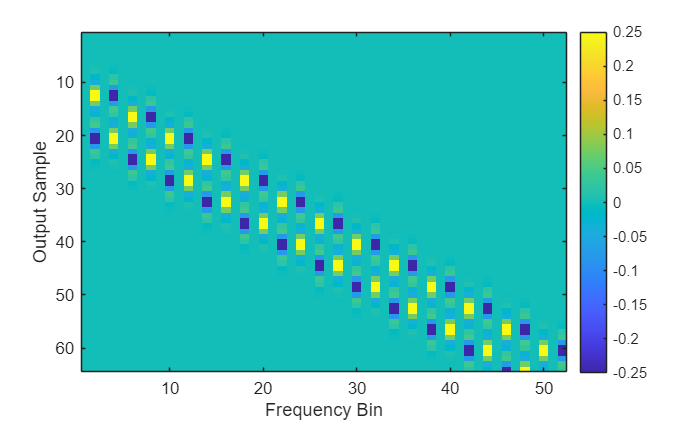


figure;
imagesc(imag(synthesis_matrix));
colormap('parula');
colorbar;
xlabel('Frequency Bin');
ylabel('Output Sample');

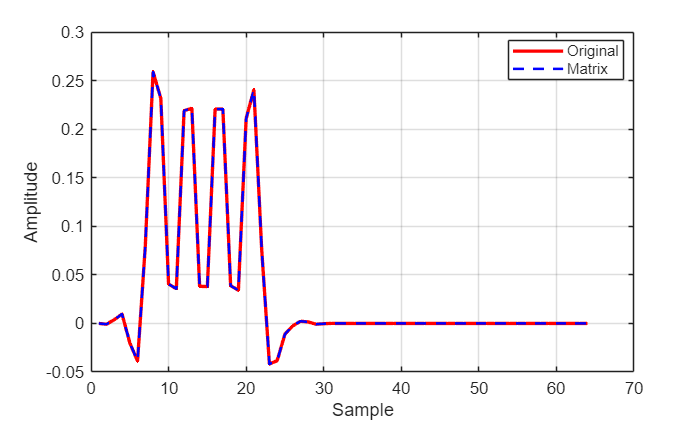


% Test reconstruction
figure;
test_pos = 9;
Xk_flat = all_Xk_flat(test_pos, :);
reconstructed_matrix = Xk_flat * synthesis_matrix_transpose;
original = all_outputs(test_pos, :);

plot(1:length(original), original, 'r-', 'LineWidth', 2);
hold on;
plot(1:length(reconstructed_matrix), reconstructed_matrix, 'b--', 'LineWidth', 1.5);
xlabel('Sample');
ylabel('Amplitude');
legend('Original', 'Matrix', 'Location', 'best');
grid on;